load("isim1.mat")
load("isim1a.mat")

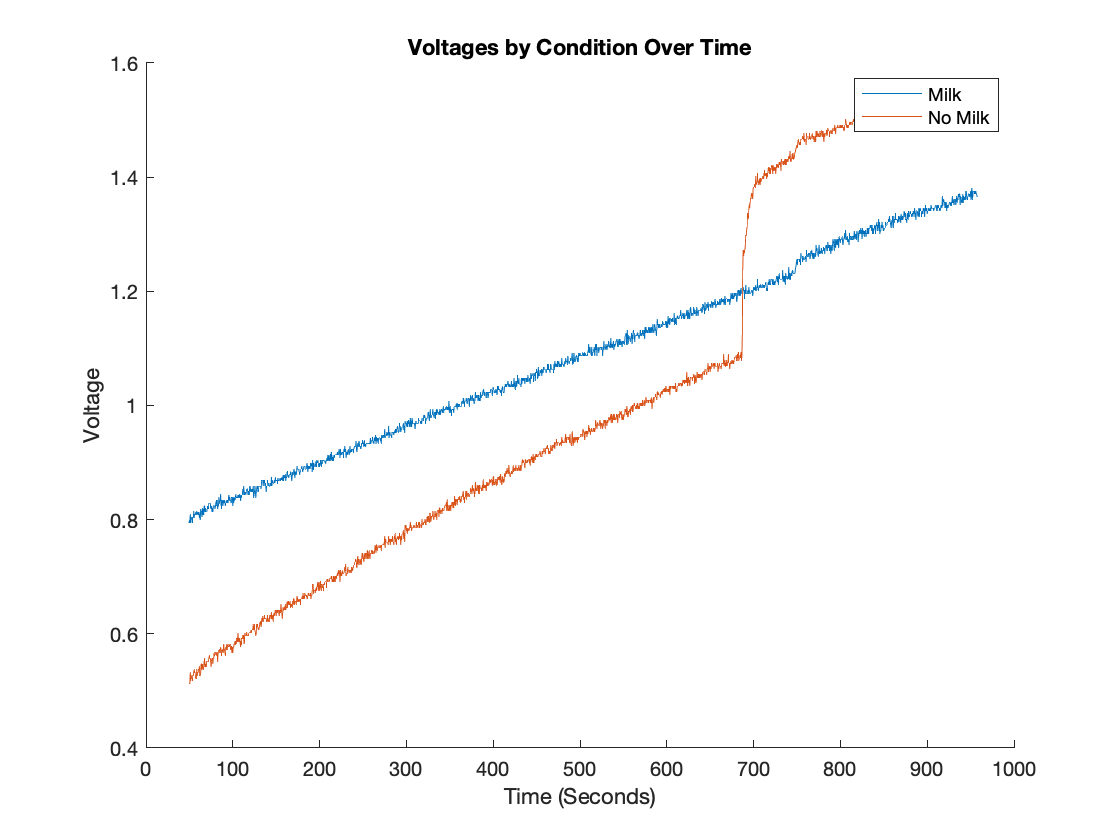

clf; hold on;
plot(time, milk_voltage);
plot(time, no_milk_voltage);

title("Voltages by Condition Over Time")
ylabel("Voltage");
xlabel("Time (Seconds)");
legend("Milk", "No Milk");
hold off;

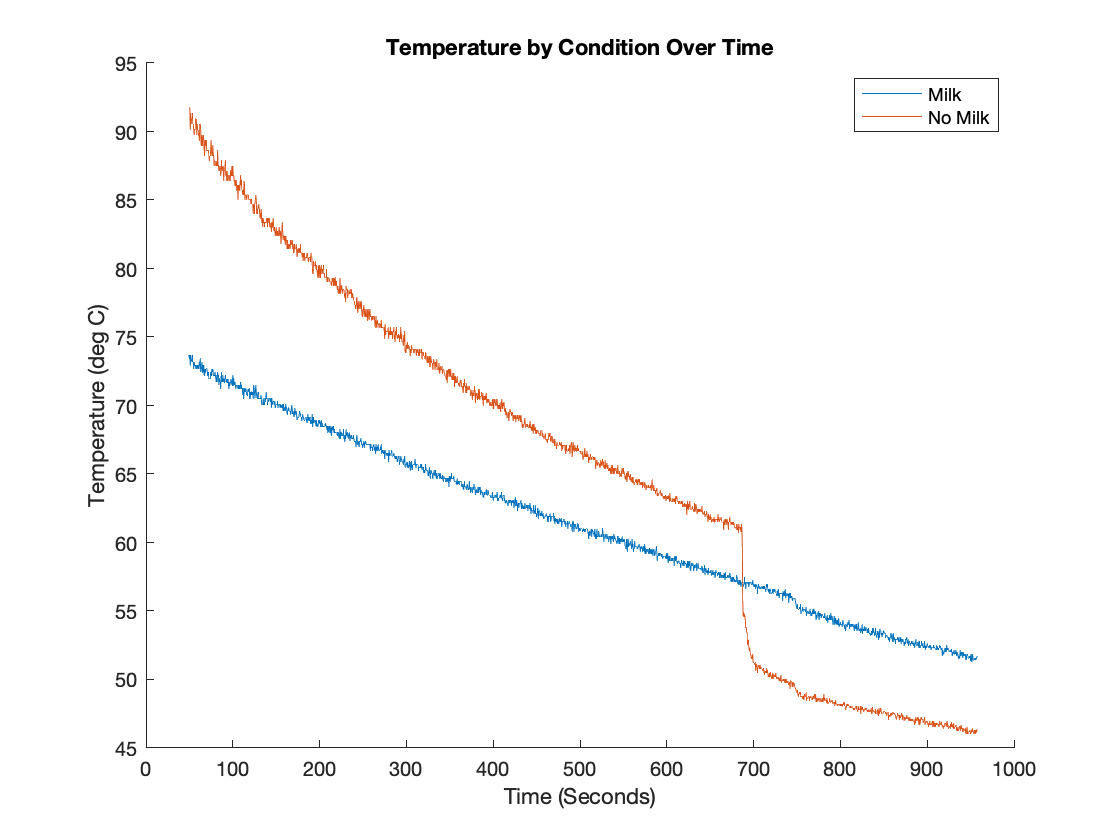

clf; hold on;
plot(time, milk_temp);
plot(time, no_milk_temp);

title("Temperature by Condition Over Time")
ylabel("Temperature (deg C)");
xlabel("Time (Seconds)");
legend("Milk", "No Milk");
hold off;

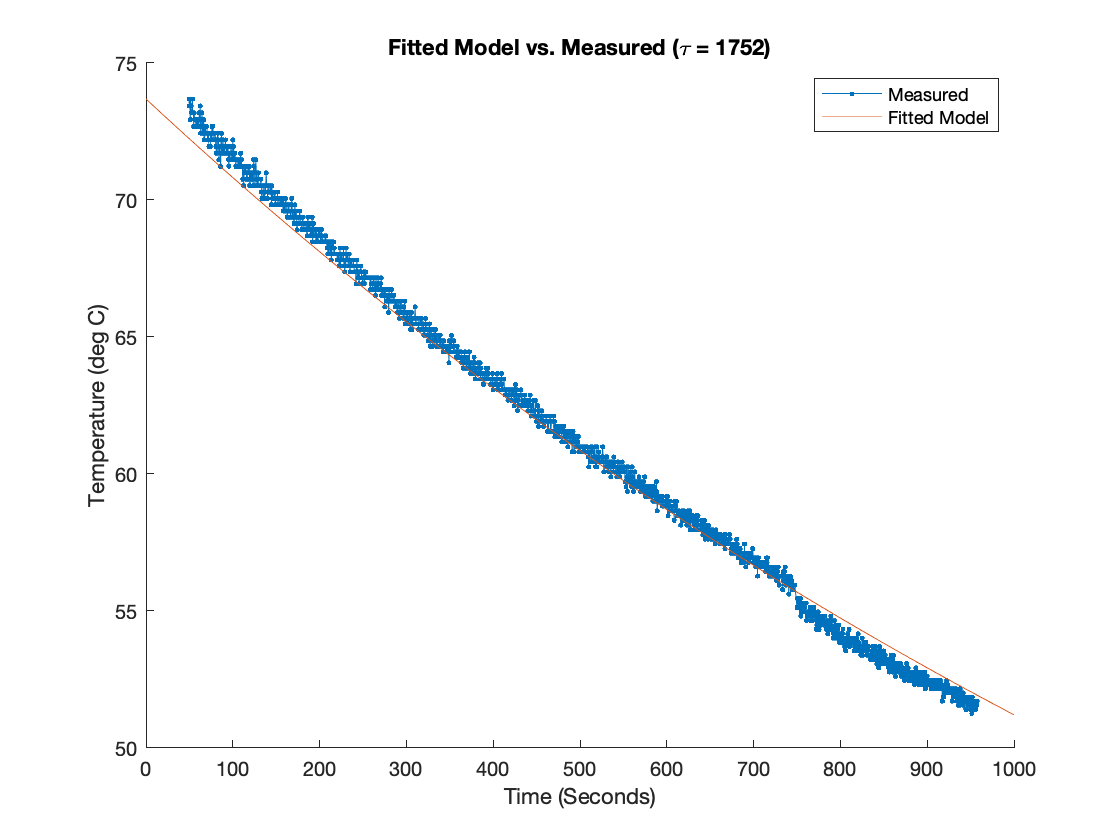

clf; hold on;
plot(time, milk_temp, '.-');

fplot(@(t) (22 + (milk_temp(1) - 22) * exp(-t / tau)))

title("Fitted Model vs. Measured (\tau = " + round(tau) + ")")
ylabel("Temperature (deg C)");
xlabel("Time (Seconds)");
xlim([0 1000])
legend("Measured", "Fitted Model");
hold off;